phi = 0;
W = 1;
D = 1;
L = 1;
rho_full = 1250;
f_rho = @(y, h) ( (y >= h)*0.5*rho_full + (y < h)*rho_full );


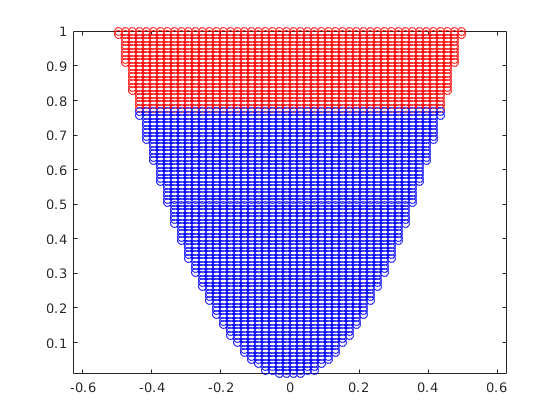

center_of_mass =     0.0000    0.5643


center_of_buoyancy =    -0.0000    0.4638


mass_boat = 2.2601e+06

mass_water = 2.2444e+06

[center_of_mass, center_of_buoyancy, mass_boat, mass_water] ...
    = boat_sim(phi, W, D, L, @(y)(f_rho(y, 0.2)), true)

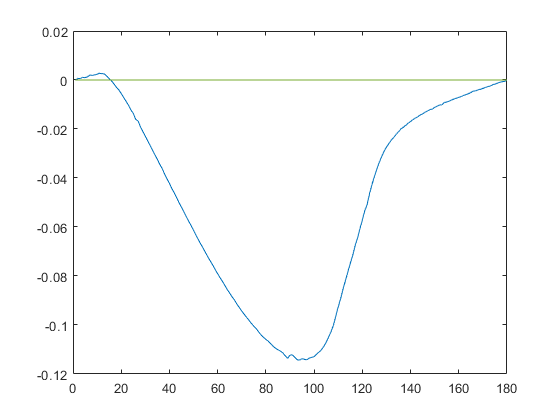

phis = 1:180;
moment_arms = zeros(length(phis));

for phi = phis
    [com, cob, ~, ~] = boat_sim(phi, W, D, L, @(x, y) abs(2*x) / W <= y, @(y) y*rho_full, false);
    moment_arms(phi) = com(1) - cob(1);
end

plot(phis, moment_arms);